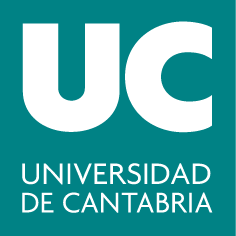

#### ***Grado en Ingeniería ****de los Recursos Energéticos / ****Grado en Ingeniería ****de los Recursos Mineros*

## **Álgebra Lineal y Geometría**

# **Práctica 1: Matrices y Sistemas de Ecuaciones Lineales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Aprender a definir y manipular matrices y vectores.

- Calcular rangos y determinantes de matrices.

- Hallar la forma escalonada reducida de una matriz.

- Resolver sistemas de ecuaciones lineales.

### Comandos útiles

#### Crear vectores y matrices

- Crear un vector fila:

a=1:2:10

a =      1     3     5     7     9


a=[1 4 9]

a =      1     4     9


a=[1, 4, 9]

a =      1     4     9


- Crear un vector columna:

b=[-1;2;3] % vector columna o matriz de 3 filas y 1 columna 

b =     -1
     2
     3


b=[-1 2 3]'% mismo vector columna, haciendo la traspuesta de un vector fila

b =     -1
     2
     3


- Para definir una matriz combinamos la definición de vectores fila y columna

M=[1 2 3; 4 5 6] % matriz de 2 filas y 3 columnas 

M =      1     2     3
     4     5     6


A=[1 2 1; 2 4 3; 3 5 2]  % matriz de 3 filas y 3 columnas 

A =      1     2     1
     2     4     3
     3     5     2


- Se pueden seleccionar elementos de una matriz, indicando la posición de la fila y la columna, o filas o columnas enteras:

A(1,3) % muestra el elemento de la primera fila y tercera columna de la matrtiz A

ans = 1

A(2,:) % extrae la fila 2 entera de la matriz A

ans =      2     4     3


A(:,1) % extrae la columna 1 entera de la matriz A

ans =      1
     2
     3


- Obtener la matriz traspuesta de una matriz A:

At = A'

At =      1     2     3
     2     4     5
     1     3     2


#### Cálculo del rango de una matriz

- `rank(A)`: Calcula el rango de una matriz A. Ejemplo:

rangoA = rank(A)

rangoA = 3

- `det(A)`: Calcula el determinante de una matriz A. Ejemplo:

determinanteA = det(A) % Al ser distinto de cero, el rango es 3

determinanteA = 1.0000

- `rref(A)`: Halla la forma escalonada reducida (y los pivotes) de una matriz A. También puede proporcionar las posiciones de las columnas pivotales. Ejemplos:

red_A = rref(A)  % El resultado es la forma escalonada de A

red_A =      1     0     0
     0     1     0
     0     0     1


[red_M, pivM] = rref(M)% hay dos resultados: la forma escalonada y las posiciones 

red_M =      1     0    -1
     0     1     2


pivM =      1     2


% de las columnas pivotales

#### Calcular la inversa de una matriz

- `inv(A)`:  Halla la inversa de una matriz A. Ejemplo:

inversaA =  inv(A)

inversaA =    -7.0000    1.0000    2.0000
    5.0000   -1.0000   -1.0000
   -2.0000    1.0000         0


#### Resolución de sistemas de ecuaciones lineales

- `linsolve(A,b)`: Resuelve un sistema de ecuaciones dada la matriz de coeficientes `A` y el vector de términos independientes `b` (solo para **sistemas compatibles determinados**). Es equivalente al operador de división a la izquierda (`A\b`). Ejemplo:

sol = linsolve(A,b) 

sol =    15.0000
  -10.0000
    4.0000


sol = A\b

sol =    15.0000
  -10.0000
    4.0000


- `solve`: Resuelve ecuaciones algebraicas y sistemas de ecuaciones. Para ello hay que trabajar con las incógnitas `x, y, z`, etc. en lenguaje simbólico definiéndolas antes de usarlas con la función `syms`, que pertene al paquete `symbolic`. Ejemplos:

syms x
valorX = solve(x^2-4==0, x) % Resuelve una ecuación algebraica con incógnita x

$$valorX = \left(\begin{array}{c} -2\\ 2 \end{array}\right)$$

syms x y z % definir variables simbólicas
X=[x y z].'; % Vector columna de incógnitas. En simbólico poner .' para la traspuesta
[solX solY solZ]=solve(A*X==b, x, y, z); % el primer argumento es la ecuación a 
% resolver, y a continuación las variables
[solX solY solZ]

$$ans = \left(\begin{array}{ccc} 15 & -10 & 4 \end{array}\right)$$

- `subs(exp, var, valor)`: Sustituye el valor de una variable en una expresión simbólica por otra expresión o valor numérico. Ejemplo:

syms x
subs(x^2 + x + 3, x, 2) % sustituye x=2 en esa ecuación de 2º grado

$$ans = 9$$

- `null(A, 'r'): `Devuelve la solución al sistema de ecuaciones homogéneo de matriz de coeficientes `A`. El argumento `'r'` es opcional. Lo usaremos habitualmente, pues da lugar a soluciones compuestas por números racionales (que se pueden expresar como una fracción), que resultan más manejables. Lógicamente, las soluciones devueltas con y sin `'r'` son igual de válidas. Ver el ejercicio resuelto 4 para la interpretación del resultado de `null`.

#### Factorización de matrices

- `lu(A)`: Proporciona la factorización de la matriz `A`. Ejemplo:

[L U P] = lu(A)

L =     1.0000         0         0
    0.6667    1.0000         0
    0.3333    0.5000    1.0000


U =     3.0000    5.0000    2.0000
         0    0.6667    1.6667
         0         0   -0.5000


P =      0     0     1
     0     1     0
     1     0     0


% Comprobación
P*A-L*U

ans =      0     0     0
     0     0     0
     0     0     0


- `chol(A, 'lower')`: Proporciona la factorización de Cholesky de la matriz `A` en base a una matriz triangular inferior.

A=[4 2 1; 2 2 0; 1 0 3];
L =  chol(A, 'lower')

L =     2.0000         0         0
    1.0000    1.0000         0
    0.5000   -0.5000    1.5811


% Comprobación
L*L'-A

ans = 1.0e-15 *

         0         0         0
         0         0         0
         0         0    0.4441


- `issymmetric(A):` Sirve para comprobar si A es una matriz simétrica. Devuelve 1 (TRUE) ó 0 (FALSE). Ejemplo:

issymmetric(A)

ans = logical
   1


#### Cambiar el formato de las salidas mostradas

- `format`: Cambia el formato de los resultados.

format rat % Para tener el resultado en formato de cociente (ratio)
format long % Para recuperar el formato decimal con 15 decimales
format short % Para recuperar el formato decimal con 4 decimales

### Ejercicios resueltos

*Nota: las lineas de código que terminan en *`;`* no muestran resultado por pantalla, mientras que la mayoría sí lo muestran, para facilitar vuestra comprobación.*

#### **Ejercicio 1: Manipulación de matrices**

Considerar la matriz *A* y hacer las siguientes transformaciones: 

a) sustituir el término (2,3) por -3 y sustituir el término (1,2) por 7.

b) extraer en un vector la primera fila de *A* y en otro vector la segunda columna de *A*.

c) extraer en una matriz las filas de 1 a 3 de *A*, y en otra matriz las columnas 3 y 4.

d) añadir una matriz identidad de orden 4 a la derecha de *A*, y lo mismo debajo de *A*.


$$A = \pmatrix{1& 3 & 2& -1\cr
                0 & 0 & 2 & 5 \cr
                -2 & 0 & 0 & 3 \cr
                1 & 1 & 1 & -1\cr}$$


a) sustituir el término (2,3) por -3 y sustituir el término (1,2) por 7.

A=[1 3 2 -1;0 0 2 5;-2 0 0 3;1 1 1 -1]; % Definir la matriz original
A(2,3)=-3

A =      1     3     2    -1
     0     0    -3     5
    -2     0     0     3
     1     1     1    -1


A(1,2)=7

A =      1     7     2    -1
     0     0    -3     5
    -2     0     0     3
     1     1     1    -1


b) extraer en un vector la primera fila de *A* y en otro vector la segunda columna de *A*.

v1=A(1,:)

v1 =      1     7     2    -1


v2=A(:,2)

v2 =      7
     0
     0
     1


c) extraer en una matriz las filas de 1 a 3 de *A*, y en otra matriz las columnas 3 y 4.

B=A(1:3,:)

B =      1     7     2    -1
     0     0    -3     5
    -2     0     0     3


C=A(:,3:4)

C =      2    -1
    -3     5
     0     3
     1    -1


d) añadir una matriz identidad de orden 4 a la derecha de *A*, y lo mismo debajo de *A*.

I4=eye(4)

I4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


A2=[A,I4] % a la derecha

A2 =      1     7     2    -1     1     0     0     0
     0     0    -3     5     0     1     0     0
    -2     0     0     3     0     0     1     0
     1     1     1    -1     0     0     0     1


A3= [A;I4] % debajo

A3 =      1     7     2    -1
     0     0    -3     5
    -2     0     0     3
     1     1     1    -1
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


#### **Ejercicio 2: Forma reducida y rango**

Dada la siguiente matriz *A*, calcular:

a) su forma escalonada reducida y rango.

b) una submatriz *M* que le proporciona el rango. Calcular el determinante e inversa de *M*. 


$$A = \pmatrix{3& 1& -8& 2& 1\cr
                -2 &2 &4 &-7& 2 \cr
                1& 11& -12& 34& -5 \cr
                1 &-5& 2& -16& 3\cr}$$


a) su forma escalonada reducida y rango.

A=[3 1 -8 2 1; -2 2 4 -7 2; 1 11 -12 34 -5; 1 -5 2 -16 3]; % Definir la matriz
[red, piv] = rref(A) % tiene 3 pivotes y las columnas pivotales son 1º,2º,3º

red =     1.0000         0         0  -33.6250   10.0000
         0    1.0000         0   -9.1250    3.0000
         0         0    1.0000  -14.0000    4.0000
         0         0         0         0         0


piv =      1     2     3


rango = rank(A) % el rango es 3, que coincide con el número de columnas pivotales

rango = 3

b) una submatriz *M* que le proporciona el rango. Calcular el determinante e inversa de *M*. 

M=A(1:3,piv) % la submatriz que proporciona el rango es aquella formada por las 3 

M =      3     1    -8
    -2     2     4
     1    11   -12


% primeras filas y las columnas pivotales
det(M) % calcular el determinante

ans = -32.0000

inv(M) % calcular la inversa

ans =     2.1250    2.3750   -0.6250
    0.6250    0.8750   -0.1250
    0.7500    1.0000   -0.2500


#### **Ejercicio 3: Resolución de sistemas de ecuaciones lineales**

Clasificar y, si se puede, resolver los sistemas dados por las siguientes parejas de matrices de coeficientes *A* y vectores de términos independientes *b*:

a) $A = \pmatrix{1 & -3 & 2 \cr
                5 & 6 & -1 \cr
                4 & 9 & 5 \cr}   $        $b=\pmatrix{1 \cr
               3 \cr
               1 \cr}$

b) $A = \pmatrix{1 & -3 & 2 \cr
                5 & 6 & -1 \cr
                4 & 9 & -3 \cr} $        $b=\pmatrix{1 \cr
               3 \cr
               1 \cr}$

c) $A = \pmatrix{2 & 3 & 1 & -5 \cr
                3 & 3 & 0 &3 \cr
                3 & 4 & 1 &-4\cr}$      $b=\pmatrix{1\cr
               3 \cr
               2 \cr}$    Dar la solución general para (x,y,z,t) y la solución particular para $z=1$y $t=2$.

a) $A = \pmatrix{1 & -3 & 2 \cr
                5 & 6 & -1 \cr
                4 & 9 & 5 \cr}   $        $b=\pmatrix{1 \cr
               3 \cr
               1 \cr}$

A = [1 -3 2; 5 6 -1; 4 9 5]; % matriz de coeficientes
b = [1 3 1]'; % términos independientes
Ampli=[A, b] % matriz ampliada

Ampli =      1    -3     2     1
     5     6    -1     3
     4     9     5     1


[rank(A) rank(Ampli)]

ans =      3     3


Por el Teorema de Rouché-Fröbenius, el sistema es compatible determinado. Por lo tanto se puede resolver de varias formas.

- Forma 1:  Utilizando la forma escalonada reducida por filas de la matriz ampliada del sistema (método de Gauss-Jordan).

format rat
red = rref(Ampli)

red =        1              0              0             43/56    
       0              1              0             -9/56    
       0              0              1             -1/8     


sol1 = red(:, 4) % leemos la solución de la última columna en forma reducida

sol1 =       43/56    
      -9/56    
      -1/8     


- Forma 2:  Con la función linsolve (usa distintos tipos de factorización de matrices para resolver el sistema).

sol2 = linsolve(A,b) 

sol2 =       43/56    
      -9/56    
      -1/8     


- Forma 3:  Con la inversa de la matriz de coeficientes

sol3 = inv(A)*b

sol3 =       43/56    
      -9/56    
      -1/8     


- Forma 4: Con el operador `\` (matrix left division). Ver ayuda con `help ldivide`.

sol4 = A\b

sol4 =       43/56    
      -9/56    
      -1/8     


- Forma 5:  Con la función solve trabajando en simbólico.

syms x y z
X=[x y z].';
[sol5X sol5Y sol5Z]=solve(A*X==b, x, y, z);
sol5 = [sol5X sol5Y sol5Z]

$$sol5 = \left(\begin{array}{ccc} \frac{43}{56} & -\frac{9}{56} & -\frac{1}{8} \end{array}\right)$$

- Forma 6: Como la matriz de coeficientes es invertible, se puede resolver el sistema usando factorización LU.

[L U P] = lu(A);
% Comprobación:
P*A-L*U

ans =        0              0              0       
       0              0              0       
       0              0              0       


Se resuelven dos sistemas asociados a las matrices triangulares L y U:  

Como $PA=LU \Rightarrow A=P^{-1}LU$, y $A\vec{x}=\vec{b}$, entonces los dos nuevos sistemas son:   


$$P^{-1}L\vec{y}=\vec{b}$$
            
$$U\vec{x}=\vec{y}$$


Para ello se puede usar cualquier técnicas de las estudiadas para resolución de sistemas compatibles determinados, por ejemplo:

y = inv(P)*L\b 

y =        3       
       2/5     
      -1       


x = U\y

x =       43/56    
      -9/56    
      -1/8     


O utilizando la inversa de la matriz de coeficientes:

y = inv(inv(P)*L)*b 

y =        3       
       2/5     
      -1       


x = inv(U)*y

x =       43/56    
      -9/56    
      -1/8     


b) $A = \pmatrix{1 & -3 & 2 \cr
                5 & 6 & -1 \cr
                4 & 9 & -3 \cr} $        $b=\pmatrix{1 \cr
               3 \cr
               1 \cr}$

A = [1 -3 2; 5 6 -1; 4 9 -3]; % matriz de coeficientes
b = [1 3 1]'; % términos independientes
Ampli=[A, b] % Obtener la matriz ampliada

Ampli =        1             -3              2              1       
       5              6             -1              3       
       4              9             -3              1       


[rank(A) rank(Ampli)] 

ans =        2              3       


Por el Teorema de Rouché-Fröbenius, el sistema es incompatible porque el rango de A y la ampliada no coinciden.

c) $A = \pmatrix{2 & 3 & 1 & -5 \cr
                3 & 3 & 0 &3 \cr
                3 & 4 & 1 &-4\cr}$      $b=\pmatrix{1\cr
               3 \cr
               2 \cr}$    

    Dar la solución general para (x,y,z,t) y la solución particular para $z=1$y $t=2$.

A = [2 3 1 -5; 3 3 0 3; 3 4 1 -4]; % matriz de coeficientes
b = [1 3 2]'; % términos independientes
Ampli=[A, b] % Obtener la matriz ampliada

Ampli =        2              3              1             -5              1       
       3              3              0              3              3       
       3              4              1             -4              2       


[rank(A) rank(Ampli)] 

ans =        2              2       


Por el Teorema de Rouché Fröbenius, el sistema es compatible indeterminado porque el rango es 2 y hay 4 incógnitas. Habrá 2 parámetros libres. Podemos resolver un sistema compatible indeterminado de varias maneras. `linsolve` no sirve porque daría solo *una* solución particular del sistema no homogéneo.

- Forma 1: Mediante la forma reducida por filas de la matriz ampliada:

RF=rref(Ampli)

RF =        1              0             -1              8              2       
       0              1              1             -7             -1       
       0              0              0              0              0       


Hay 2 parámetros libres, las que corresponden a columnas no pivotales en el sistema equivalente que define `RF`. Despejamos las variables de las columnas pivotales `(x, y)` en función de los parámetros libres `(z,t)`.

syms z t; x=2+z-8*t; y=-1-z+7*t; 
SG=[x,y,z,t] % Solución general en forma vectorial

$$SG = \left(\begin{array}{cccc} z-8\,t+2 & 7\,t-z-1 & z & t \end{array}\right)$$

Obtenemos la solución particular sustituyendo `z, t` por sus valores (ver enunciado):

SP=subs(SG,[z,t], [1,-2])

$$SP = \left(\begin{array}{cccc} 19 & -16 & 1 & -2 \end{array}\right)$$

- Forma 2: Mediante la instrucción solve:

syms x y z t  
X=[x y z t ].'; % Definir variables simbólicas y crear vector de incógnitas
[solX solY]=solve(A*X==b, x, y); % solo resolvemos en función de las variables de
% las columnas pivotales (x,y)
SG=[solX solY z t] % Sol. general

$$SG = \left(\begin{array}{cccc} z-8\,t+2 & 7\,t-z-1 & z & t \end{array}\right)$$

Obtenemos la solución particular sustituyendo `z, t` por sus valores (ver enunciado):

SP=subs(SG,[z,t], [1,-2])

$$SP = \left(\begin{array}{cccc} 19 & -16 & 1 & -2 \end{array}\right)$$

#### **Ejercicio 4: Resolución de sistemas homogéneos**

Hallar la solución de los sistemas de ecuaciones homogéneos dados por las siguientes matrices de coeficientes:

a) $A = \pmatrix{ 1& -3 & 4\cr
  1 & -2 & 5\cr
  2 & -1 & -3\cr}$              b) $A = \pmatrix{ 2 & 1 & 1\cr
  3 & 0 & -1\cr
  10 & 5 & 5\cr}$

Los sistemas de ecuaciones homogéneos son siempre compatibles, pues al menos tendrán la solución trivial. Se pueden resolver por cualquiera de los métodos vistos anteriormente para sistemas compatibles determinados o mediante el comando `null`.

A = [1 -3 4; 1 -2 5; 2 -1 -3]; % matriz de coeficientes
solh = null(A, 'r')


solh =

  3×0 empty double matrix



Este resultado indica que la única solución es la trivial, ($x=0, y=0, z=0$), así que es un sistema compatible determinado.

b) $A = \pmatrix{ 2 & 1 & 1\cr
  3 & 0 & -1\cr
  10 & 5 & 5\cr}$

format rat
A = [2 1 1; 3 0 -1; 10 5 5];
solh = null(A, 'r')

solh =        1/3     
      -5/3     
       1       


En este caso es un sistema compatible indeterminado, con infinitas soluciones, puesto que el resultado de `null` no es la solución trivial. La solución del sistema vendrá dada por la combinación lineal de los vectores en las columnas de la matriz que devuelve `null`. En este caso, devuelve una única columna, por lo que la solución del sistema será: $\alpha\Big(\frac{1}{3},\frac{-5}{3}, 1\Big)  \forall \alpha \in \mathbb{R}$

#### **Ejercicio 5: Resolución de sistemas mediante la factorización de Cholesky**

Resolver, utilizando la factorización de Cholesly, el sistema de ecuaciones dado por la siguiente matrices de coeficientes *A* y el vector de términos independientes *b:*


$$A = \pmatrix{ 4 & 2 & 1\cr
  2 & 2 & 0\cr
  1 & 0 & 3\cr}$$
     
$$b=\pmatrix{2\cr
               -3 \cr
               5 \cr}$$


En primer lugar, creamos la matriz A y el vector b y comprobamos que A es simétrica y definido positiva:

A=[4 2 1; 2 2 0; 1 0 3]; 
b=[2 -3 5]';
issymmetric(A) % es simétrica puesto que devuelve 1 (1=TRUE)

ans = logical
   1


Los menores principales de primer orden (4, 2, 3) son positivos. Calculamos los menores principales de orden 2 y 3:

[det(A(1:2, 1:2)), det(A(2:3, 2:3)), det(A([1 3],[1 3])), det(A)]

ans =        4              6             11             10       


Como todos los menores principales son positivos, A es una matriz definida positiva. Se puede aplicar la factorización de Cholesky:

format short
L = chol(A, 'lower')

L =     2.0000         0         0
    1.0000    1.0000         0
    0.5000   -0.5000    1.5811


A - L*L' % comprobación

ans = 1.0e-15 *

         0         0         0
         0         0         0
         0         0   -0.4441


Como $A=LL^{t} $ y $A\vec{x}=\vec{b}$, entonces los dos nuevos sistemas, en los que interviene la matriz triangular L, son:   


$$L\vec{y}=\vec{b}$$
            
$$L^{t}\vec{x}=\vec{y}$$


y = L\b

y =     1.0000
   -4.0000
    1.5811


x = L'\y

x =     2.0000
   -3.5000
    1.0000


O utilizando la inversa de la matriz de coeficientes:

y = inv(L)*b;
x = inv(L')*y

x =     2.0000
   -3.5000
    1.0000


### Ejercicios propuestos

Se propone resolver con Matlab los ejercicios de las hojas de problemas de los temas 1 y 2, en especial: **1.6, 1.7, 1.9, 1.15, 1.16** del tema 1 y **2.3, 2.4, 2.11, 2.12, 2.13 **del tema 2.